# Approximating Higher Order Derivatives

Do not edit. This code loads and plots the space shuttle data from NASA. 

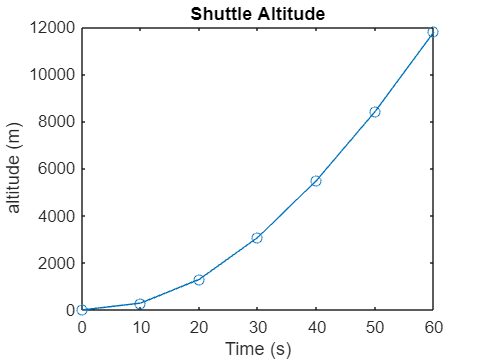

timeFromNASA = 0:10:60;
heightFromNASA = [2.2 293 1300 3085 5500 8428 11796];

plot(timeFromNASA,heightFromNASA,"o-")
title("Shuttle Altitude")
xlabel("Time (s)")
ylabel("altitude (m)")

## Task 1

In a previous chapter, you approximated the first derivative of position (also known as the velocity) of a launched shuttle. 

v=dh/dt 

But why stop there? You can approximate higher-order derivatives of position, too!

Task

The time between successive points in `timeFromNASA` is 10 seconds. Store this value in a variable `dt`. 

dt=10

dt = 10

## Task 2

The `diff` function takes the difference between successive elements in an array `A`. 

`dA` `=` `diff``(``A``)`

Task

Compute the difference between each successive point in `heightFromNASA` and store the result in an array `dh`.

dh=diff(heightFromNASA)

dh = 1.0e+03 *

    0.2908    1.0070    1.7850    2.4150    2.9280    3.3680


## Task 3

Find the average velocity of the space shuttle by dividing `dh` by `dt`. Store this in an array called `v`. 

v=dh./dt

v =    29.0800  100.7000  178.5000  241.5000  292.8000  336.8000


## Task 4

You can display functions in bar graphs using the `bar` function.

`bar``(``y``)`

You can also label the y-axis using the `ylabel` function. 

`ylabel``(``"text"``)`

Task

Create a bar graph of the velocity values. Use `ylabel` to label the y-axis `"Velocity"`.

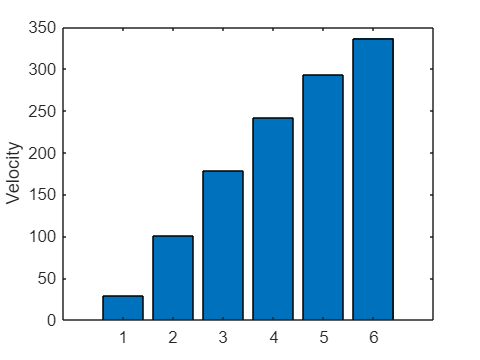

bar(v)
ylabel("Velocity")

## Task 5

As you can see from the bar  graph of velocity, the  velocity of the shuttle is increasing with time! Let's repeat the  process and find the acceleration of the shuttle, which is the  derivative of velocity.

a=dv/dt

Task

-  Compute the difference in velocity between each successive element in array `v` and store the result in an array `dv`. 

-  Calculate the average acceleration of the shuttle by dividing `dv` by `dt` and store this result in an array `a`. 

-  Create a bar graph of the acceleration values and label the y-axis `"Acceleration"`.

dv=diff(v)

dv =    71.6200   77.8000   63.0000   51.3000   44.0000


a=dv./dt

a =     7.1620    7.7800    6.3000    5.1300    4.4000


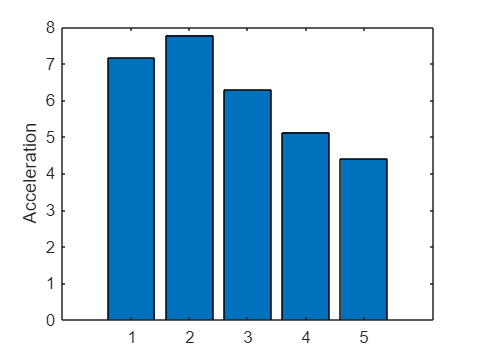

bar(a)
ylabel("Acceleration")

## Task 6

Velocity and acceleration are the first and second  derivatives of position (or height in this example). However, in this  example acceleration is also a function of time, which means that you  can take the derivative of it, too! 

Task

Repeat the process from Task 5 to compute and visualize the rate-of-change of acceleration. This is a quantity called *jerk*. 

-  Compute the change in acceleration, `da`. 

-  Compute the average jerk, `J`. 

-  Create a bar graph displaying the jerk values. Add the label `"Jerk"` to the y-axis. 

da=diff(a)

da =     0.6180   -1.4800   -1.1700   -0.7300


J=da./dt

J =     0.0618   -0.1480   -0.1170   -0.0730


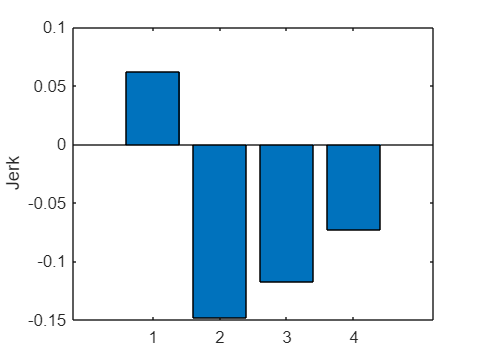

bar(J)
ylabel("Jerk")

## Further Practice

Many applications require us to solve for the position of moving  objects. However, typically we only have information regarding their  accelerations, which is the second derivative of position. 

a=dv/dt=d2y/dt2

 The following sections will show you how to handle such situations in MATLAB.